## **Defining the parameter**

m_pendulum = 10/1000 ; %the mass of pendulum in gram

r = 35/1000 ; %length of arm in mm

l = (107/1000)/2; %length of arm of pendulum in mm

J_arm= motor_j ; % J equivilant inertia for the arm from parameter estimation

b_eq=motor_b ; %damping equivlant measured from parameter estimation 

% Defining some constant for the system for sake of simplifing 
a=J_arm+(m_pendulum*r*r)

a = 0.2760

b=m_pendulum*l*r

b = 1.8725e-05

c=(4/3)*m_pendulum*l*l

c = 3.8163e-05

d=m_pendulum*9.8*l

d = 0.0052

e=(a*c)-(b*b)

e = 1.0533e-05

% Defining motor parametr
motor_effeciency = 0.69

motor_effeciency = 0.6900

gear_box_effeciency = 0.9

gear_box_effeciency = 0.9000

gear_box_ratio = 110 % motor -> load 

gear_box_ratio = 110

G = ((motor_effeciency*gear_box_effeciency*motor_k*motor_k*(gear_box_ratio*gear_box_ratio))-(motor_b*motor_r))/(motor_r)

G = 5.1085e+03

H= (motor_effeciency*gear_box_effeciency*motor_k*gear_box_ratio)/(motor_r*e)

H = 1.0097e+07

## **Defining the State space coffecient **

A_mat=[0 0 1 0;0 0 0 1;0 (b*d)/(e) (-(c*G)/e) 0 ; 0 ((a*d)/e) (-b*G)/e 0 ];
B_mat=[0;0;(c)*(H);(b)*(H)]; % the input is voltage of the motor
C_mat=[1 0 0 0 ; 0 1 0 0];
D_mat=[0;0];

## State space matrix

state_space_model=ss(A_mat,B_mat,C_mat,D_mat);

## LQR parameter

q=diag([1 500 20 500]);% state matrix [theta alpha thetadot alphadot]
r_eq=0.01;
k=lqr(state_space_model,q,r_eq);
k

k = 	1.0e+03 *

   -0.0100    3.8745   -0.1157    0.3986


k_theta=k(1)

k_theta = -10.0000

k_alpha=k(2)

k_alpha = 3.8745e+03

k_thetadot=k(3)

k_thetadot = -115.7416

k_alphadot=k(4)

k_alphadot = 398.6310

syslqr=ss(A_mat-B_mat*k,B_mat,C_mat,0);


## FeedBack Control

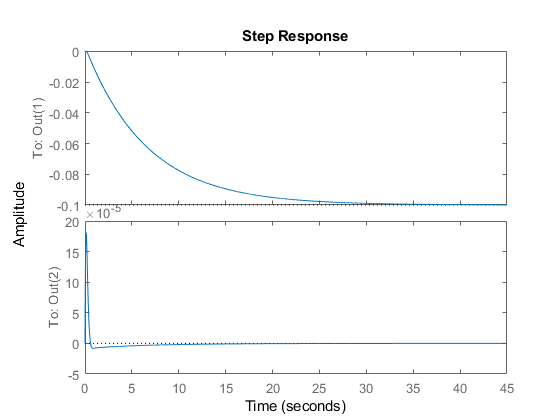

step(syslqr)